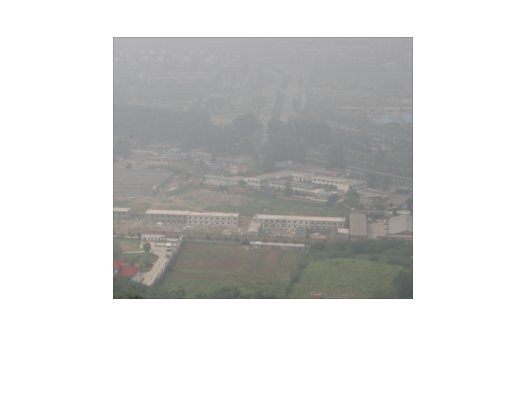

clc;
image=imread("Ex_ColorEnhance.png");
imshow(image);

r_pic1=image(:,:,1);
g_pic1=image(:,:,2);
b_pic1=image(:,:,3);
[m,n]=size(r_pic1);
empty_r=zeros(m,n);
empty_g=zeros(m,n);
empty_b=zeros(m,n);
histgram_r=get_hist(r_pic1);
histgram_g=get_hist(g_pic1);
histgram_b=get_hist(b_pic1);
for i=1:m
    for j=1:n
        patch_r=get_patch(45,i,j,r_pic1);
        patch_g=get_patch(45,i,j,g_pic1);
        patch_b=get_patch(45,i,j,b_pic1);
        empty_r(i,j)=heq(255,r_pic1(i,j),patch_r);
        empty_g(i,j)=heq(255,g_pic1(i,j),patch_g);
        empty_b(i,j)=heq(255,b_pic1(i,j),patch_b);
    end
end
empty_r=uint8(empty_r)

empty_r = 262×300 uint8 矩阵
     0    21    20    19    19    19    13    13    18    18    17    17    13    12    12    12    12    12    12    16    16    16    12     8     8     8     9     9     9     9     9     9    10    10    10    11    10    10    10    10    10    10    10    11    11     3     4     4     4     4
    21   249   242   242   249   206   242   203   239   238   238   198   238   198   198   238   237   237   236   237   237   238   238   199   238   239   201   239   238   243   244   240   240   240   206   240   240   239   239   209   239   210   239   239   239   239   239   217   186   218
    20   249   249   250   250   243   206   158   203   201   239   200   239   200   200   239   200   237   237   238   238   238   239   201   239   240   203   239   239   239   240   240   240   240   240   240   240   209   210   211   211   212   239   239   239   217   239   218   219   220
    19   249   250   250   244   209   208   207   204   203   202   2

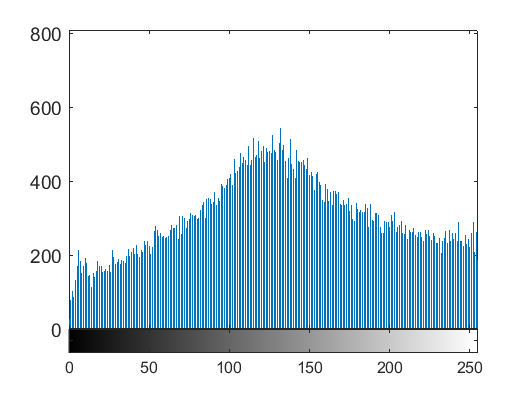

empty_g=uint8(empty_g);
empty_b=uint8(empty_b);
imhist(empty_r);

result=zeros(m,n,3);
result(:,:,1)=empty_r;
result(:,:,2)=empty_g;
result(:,:,3)=empty_b;
result=uint8(result)

result = 262×300×3 uint8 数组
result(:,:,1) =

     0    21    20    19    19    19    13    13    18    18    17    17    13    12    12    12    12    12    12    16    16    16    12     8     8     8     9     9     9     9     9     9    10    10    10    11    10    10    10    10    10    10    10    11    11     3     4     4     4     4    11     4     4    11     5     5     5     6     6     6     6    11    11    11    11    11    11    11     7     7     7    11    11     8    11     8     8     8     8     8     8     8     8    11     8     8     9    11    11     9     9     9     9     9    10    10    10    10    10    10    10     0    10    10    10    10    10    10    10    10    11    11    11     2    11    11    11    11    11    11    11    11    11    11     5    11    11     6     6    11    11     7     7     7     7     3     8     8     8     8     4     4     4     4     4     4     5     5    10    10    10    10    10    10     7     7     3     7     7 

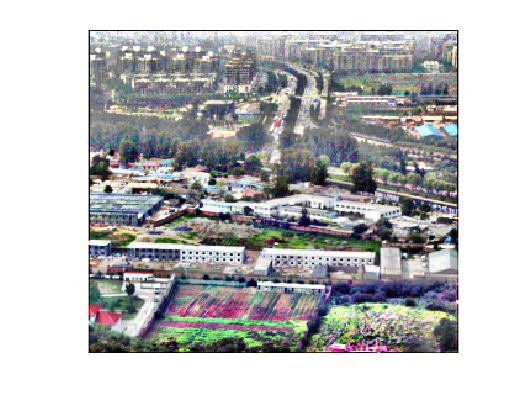

imshow(result);

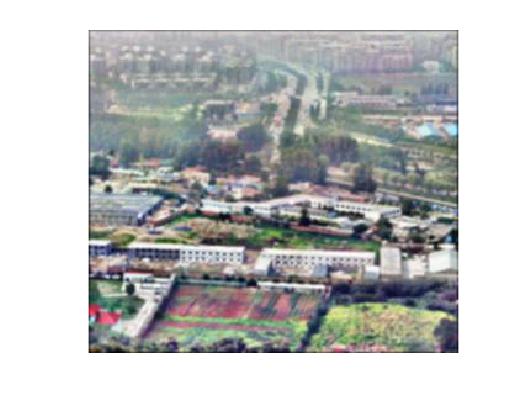

imshow("Post_ColorEnhance.jpg");